% 4 Laboratorinis darbas
% 2026-10-05
% Rezultatu grafinis 3D atvaizdavimas
% 7 variantas
%EIf-25 Jevgenij Malinkov
% 1a)
[x, y] = meshgrid(linspace(-1, 1, 50));
r = sqrt(x.^2 + y.^2);
z = exp(r.^2);

figure
h = surf(x, y, z)

h =   Surface with properties:

       EdgeColor: [0.1294 0.1294 0.1294]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [50×50 double]
           YData: [50×50 double]
           ZData: [50×50 double]
           CData: [50×50 double]

  Show all properties


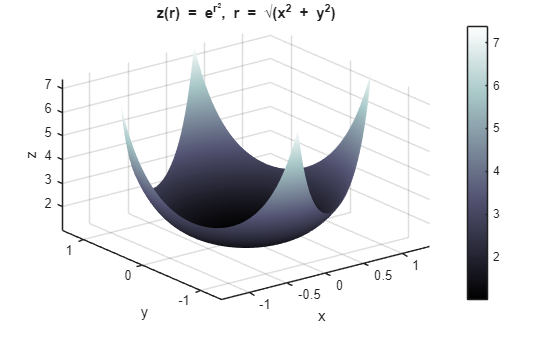

colormap(bone)                
shading interp                   
rotate(h, [0 0 1], 30)           
axis tight; grid on
xlabel('x'); ylabel('y'); zlabel('z')
title('z(r) = e^{r^2}, r = \surd(x^2 + y^2)')
colorbar
view(3)


% 1b)
[x, y] = meshgrid(linspace(-2, 1, 50))

x =    -2.0000   -1.9388   -1.8776   -1.8163   -1.7551   -1.6939   -1.6327   -1.5714   -1.5102   -1.4490   -1.3878   -1.3265   -1.2653   -1.2041   -1.1429   -1.0816   -1.0204   -0.9592   -0.8980   -0.8367   -0.7755   -0.7143   -0.6531   -0.5918   -0.5306   -0.4694   -0.4082   -0.3469   -0.2857   -0.2245   -0.1633   -0.1020   -0.0408    0.0204    0.0816    0.1429    0.2041    0.2653    0.3265    0.3878    0.4490    0.5102    0.5714    0.6327    0.6939    0.7551    0.8163    0.8776    0.9388    1.0000
   -2.0000   -1.9388   -1.8776   -1.8163   -1.7551   -1.6939   -1.6327   -1.5714   -1.5102   -1.4490   -1.3878   -1.3265   -1.2653   -1.2041   -1.1429   -1.0816   -1.0204   -0.9592   -0.8980   -0.8367   -0.7755   -0.7143   -0.6531   -0.5918   -0.5306   -0.4694   -0.4082   -0.3469   -0.2857   -0.2245   -0.1633   -0.1020   -0.0408    0.0204    0.0816    0.1429    0.2041    0.2653    0.3265    0.3878    0.4490    0.5102    0.5714    0.6327    0.6939    0.7551    0.8163    0.8776    0.9388    1

y =    -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000
   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1.9388   -1

f = 1 - 2*x.^2 - 3*y.^2

f =   -19.0000  -18.5177  -18.0504  -17.5981  -17.1608  -16.7384  -16.3311  -15.9388  -15.5614  -15.1991  -14.8517  -14.5194  -14.2020  -13.8996  -13.6122  -13.3399  -13.0825  -12.8401  -12.6127  -12.4002  -12.2028  -12.0204  -11.8530  -11.7005  -11.5631  -11.4406  -11.3332  -11.2407  -11.1633  -11.1008  -11.0533  -11.0208  -11.0033  -11.0008  -11.0133  -11.0408  -11.0833  -11.1408  -11.2132  -11.3007  -11.4032  -11.5206  -11.6531  -11.8005  -11.9629  -12.1404  -12.3328  -12.5402  -12.7626  -13.0000
  -18.2766  -17.7943  -17.3269  -16.8746  -16.4373  -16.0150  -15.6077  -15.2153  -14.8380  -14.4756  -14.1283  -13.7959  -13.4786  -13.1762  -12.8888  -12.6164  -12.3590  -12.1166  -11.8892  -11.6768  -11.4794  -11.2970  -11.1295  -10.9771  -10.8397  -10.7172  -10.6097  -10.5173  -10.4398  -10.3773  -10.3299  -10.2974  -10.2799  -10.2774  -10.2899  -10.3174  -10.3599  -10.4173  -10.4898  -10.5773  -10.6797  -10.7972  -10.9296  -11.0771  -11.2395  -11.4169  -11.6093  -11.8167  -12.0392  -12


figure
h = surf(x, y, f)

h =   Surface with properties:

       EdgeColor: [0.1294 0.1294 0.1294]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [50×50 double]
           YData: [50×50 double]
           ZData: [50×50 double]
           CData: [50×50 double]

  Show all properties


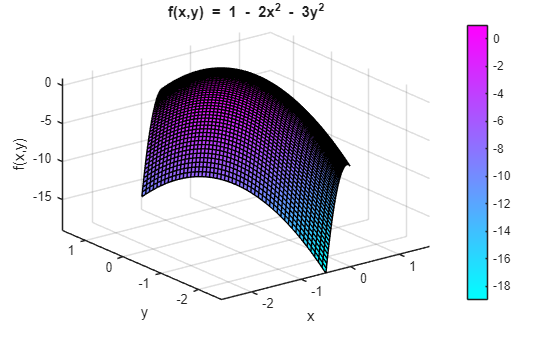

colormap(cool)
shading faceted                 
rotate(h, [0 0 1], 45)         
axis tight; grid on
xlabel('x'); ylabel('y'); zlabel('f(x,y)')
title('f(x,y) = 1 - 2x^2 - 3y^2')
colorbar
view(3)

clear
clear all
%Papildomas Funkcijos shading savybes 7 variantas
[x, y] = meshgrid(linspace(-1, 1, 30))

x =    -1.0000   -0.9310   -0.8621   -0.7931   -0.7241   -0.6552   -0.5862   -0.5172   -0.4483   -0.3793   -0.3103   -0.2414   -0.1724   -0.1034   -0.0345    0.0345    0.1034    0.1724    0.2414    0.3103    0.3793    0.4483    0.5172    0.5862    0.6552    0.7241    0.7931    0.8621    0.9310    1.0000
   -1.0000   -0.9310   -0.8621   -0.7931   -0.7241   -0.6552   -0.5862   -0.5172   -0.4483   -0.3793   -0.3103   -0.2414   -0.1724   -0.1034   -0.0345    0.0345    0.1034    0.1724    0.2414    0.3103    0.3793    0.4483    0.5172    0.5862    0.6552    0.7241    0.7931    0.8621    0.9310    1.0000
   -1.0000   -0.9310   -0.8621   -0.7931   -0.7241   -0.6552   -0.5862   -0.5172   -0.4483   -0.3793   -0.3103   -0.2414   -0.1724   -0.1034   -0.0345    0.0345    0.1034    0.1724    0.2414    0.3103    0.3793    0.4483    0.5172    0.5862    0.6552    0.7241    0.7931    0.8621    0.9310    1.0000
   -1.0000   -0.9310   -0.8621   -0.7931   -0.7241   -0.6552   -0.5862   -0.5172   -0.4483   

y =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310   -0.9310
   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621   -0.8621
   -0.7931   -0.7931   -0.7931   -0.7931   -0.7931   -0.7931   -0.7931   -0.7931   -0.7931   

z = 1 - (x.^2 + y.^2)

z =    -1.0000   -0.8668   -0.7432   -0.6290   -0.5244   -0.4293   -0.3436   -0.2675   -0.2010   -0.1439   -0.0963   -0.0583   -0.0297   -0.0107   -0.0012   -0.0012   -0.0107   -0.0297   -0.0583   -0.0963   -0.1439   -0.2010   -0.2675   -0.3436   -0.4293   -0.5244   -0.6290   -0.7432   -0.8668   -1.0000
   -0.8668   -0.7337   -0.6100   -0.4958   -0.3912   -0.2961   -0.2105   -0.1344   -0.0678   -0.0107    0.0369    0.0749    0.1034    0.1225    0.1320    0.1320    0.1225    0.1034    0.0749    0.0369   -0.0107   -0.0678   -0.1344   -0.2105   -0.2961   -0.3912   -0.4958   -0.6100   -0.7337   -0.8668
   -0.7432   -0.6100   -0.4863   -0.3722   -0.2675   -0.1724   -0.0868   -0.0107    0.0559    0.1130    0.1605    0.1986    0.2271    0.2461    0.2556    0.2556    0.2461    0.2271    0.1986    0.1605    0.1130    0.0559   -0.0107   -0.0868   -0.1724   -0.2675   -0.3722   -0.4863   -0.6100   -0.7432
   -0.6290   -0.4958   -0.3722   -0.2580   -0.1534   -0.0583    0.0273    0.1034    0.1700   

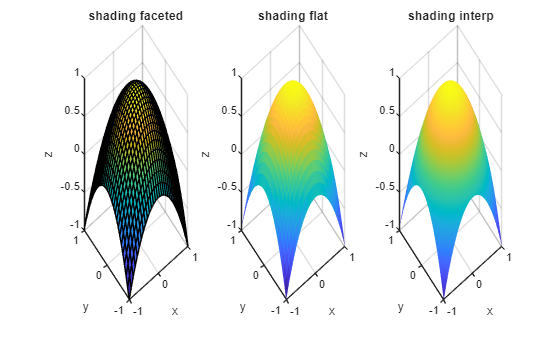


figure

subplot(1,3,1)
surf(x, y, z)
shading faceted;
title('shading faceted')
xlabel('x'); ylabel('y'); zlabel('z')
grid on

subplot(1,3,2)
surf(x, y, z)
shading flat;
title('shading flat')
xlabel('x'); ylabel('y'); zlabel('z')
grid on

subplot(1,3,3)
surf(x, y, z)
shading interp
title('shading interp')
xlabel('x'); ylabel('y'); zlabel('z')
grid on